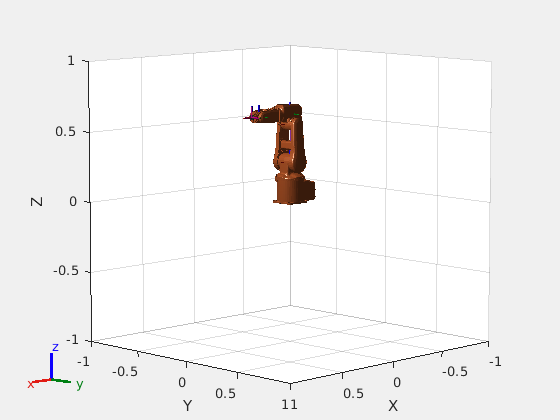

robot = loadrobot("abbIrb120");
show(robot);

config = robot.homeConfiguration;
config(1).JointPosition = 1.6995357;
config(2).JointPosition = 0.7211424;
config(3).JointPosition = 0.7489957;
config(4).JointPosition = -0.00507998;
config(5).JointPosition = -1.2084407;
config(6).JointPosition = 0.00998832;

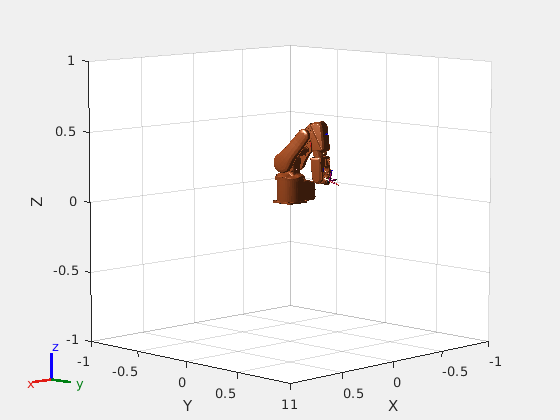

show(robot,config);

newpose = getTransform(robot,config,"link_6");
disp('POSE by joint angles for neural network:')

POSE by joint angles for neural network:


disp(newpose(1,4));

   -0.0450



disp(newpose(2,4));

    0.3449



disp(newpose(3,4));

    0.1807



### ACTUAL KINEMATICS

pos = [-0.0071599 0.33477 0.18289];
posvec = trvec2tform(pos);
disp(posvec);

    1.0000         0         0   -0.0072
         0    1.0000         0    0.3348
         0         0    1.0000    0.1829
         0         0         0    1.0000




ik = inverseKinematics("RigidBodyTree",robot);
weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robot);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);
disp(solnInfo);

           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0805e-10
             ExitFlag: 1
               Status: 'success'



for i =1:6
    disp(configSoln(i).JointPosition);
end

    1.5950

    0.5887

    0.7536

    0.0274

   -0.5079

     0



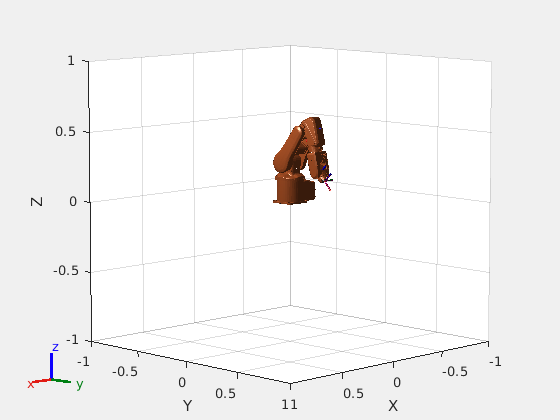

pose = getTransform(robot,configSoln,"link_6");
%disp(pose(2,4));
%disp(pose(3,4));
show(robot,configSoln);